# Allocating Resources After a Major Weather Event

## **Content:**

### Background and Scope 

- Import the Data

- Two States Most Impacted by Harvey

- Table of Events for Two Most Impacted States

### Visualizations

- Figure of Event Types

- Figure of Event Locations

### Analysis

- Three Counties with Most Events in State 1

- Three Counties with Most Events in State 2

- Three Counties with Highest Property Cost in State 1

- Three Counties with Highest Property Cost in State 2

### Conclusions and Recommendations

## Background and Scope

### Import the Data

To import the required file in the MATLAB workspace:

- Double-click the file through your matlab window only, to import it, in our case it is (.csv) type file.

- While we are working on (.csv) type file we can import the perticular column in our script, or we can import the file as it is.

-  After this we are all set to analyse our data.

### Two States Most Impacted by Harvey

To filter out the Harvey related events we created a variable `HarveyRelatedEvents `containing the data of events occured from "17th of Aug" to "3rd of Sept", by this we have successfully filtered out the duration of events in which the Harvey occured.

To filter the data for more accurate assumption we have filtered the state where Harvey occured and stored that in the variable `HarveyEvents`. After this filtering we also removed the state with undefined entries in tthe `HarveyEvents`.

Now to extract the state name from the table I first use the groupsummary() function to and then sort the table with respect to GroupCount in descending order. Then created two variables named state1 and state2 to store the first twi values of the sorted data.

HarveyRelatedEvents = StormEvents2017finalProject(StormEvents2017finalProject.Begin_Date_Time >= '2017-08-17 00:00:00' & StormEvents2017finalProject.Begin_Date_Time < '2017-09-03 23:23:01',:);
HarveyEvents = HarveyRelatedEvents(ismember(HarveyRelatedEvents.State,{'ARKANSAS','KENTUCKY','LOUISIANA','MISSISSIPPI','NORTH CAROLINA','TENNESSEE','TEXAS'}),:);
HarveyEvents = HarveyEvents(~ismissing(HarveyEvents.State),:);
HarveyState = groupsummary(HarveyEvents,'State');
HarveyState = sortrows(HarveyState,'GroupCount','descend')

HarveyState = 7×2 table
        State         GroupCount
    ______________    __________

    TEXAS                275    
    LOUISIANA             86    
    NORTH CAROLINA        59    
    ARKANSAS              53    
    TENNESSEE             46    
    MISSISSIPPI           39    
    KENTUCKY              21    


State1 = HarveyState.State(1)

State1 = categorical
     TEXAS 


State2 = HarveyState.State(2)

State2 = categorical
     LOUISIANA 


### Table of Events for Two Most Impacted States

I named a variable `EventsOnMostImpactedState` to store a table containing inforation about the two states which are heavily affected by the harvey, I filltered the categorical variable state by applying conditional operation. The other useless categories of variable state were removed by the function `removecats()` and overted on the same table variable `EventsOnMostImpactedState` 

EventsOnMostImpactedState = HarveyEvents(HarveyEvents.State == State1 | HarveyEvents.State == State2,:);
EventsOnMostImpactedState.State = removecats(EventsOnMostImpactedState.State);
EventsOnMostImpactedState.Event_Type = removecats(EventsOnMostImpactedState.Event_Type)

EventsOnMostImpactedState = 361×8 table
    State       Event_Type          CZ_Name        Begin_Date_Time         End_Date_Time       Property_Cost    Begin_Lat    Begin_Lon
    _____    _________________    ___________    ___________________    ___________________    _____________    _________    _________

    TEXAS    Tropical Storm       MONTGOMERY     2017-08-25 12:00:00    2017-08-30 00:00:00         7e+09           NaN           NaN 
    TEXAS    Tropical Storm       FORT BEND      2017-08-26 00:00:00    2017-08-30 00:00:00         8e+09           NaN           NaN 
    TEXAS    Tropical Storm       GALVESTON      2017-08-25 12:00:00    2017-08-30 00:00:00         1e+10           NaN           NaN 
    TEXAS   

## Visualizations

### Figure of Event Types

I used the heat map function to generate a figure of events perfectly explainig the data and giving a clear idea about the states affected by the harvey.

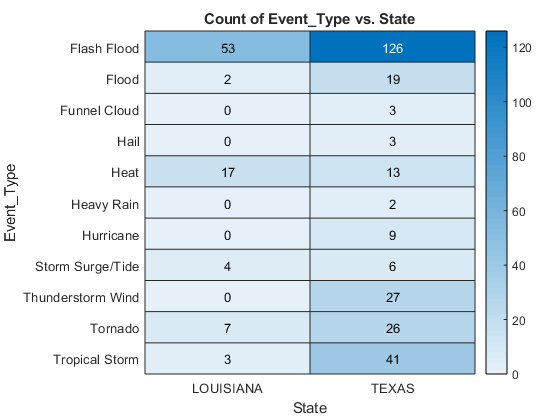

ans =   HeatmapChart (Count of Event\_Type vs. State) with properties:

      SourceTable: [361×8 table]
        XVariable: 'State'
        YVariable: 'Event_Type'
    ColorVariable: ''
      ColorMethod: 'count'

  Show all properties


heatmap(EventsOnMostImpactedState,'State','Event_Type')

### Figure of Event Locations

To show the location of the events, I first created two different variable to differentiate the Longitude and latitude of the states. Then used the geoscatter plot to plot the locations, now to plot them with different colour I used hod function to do this.

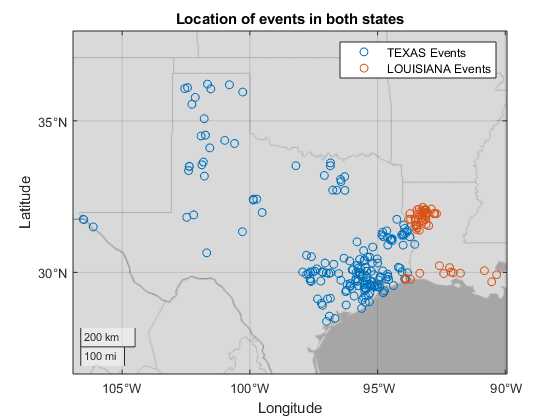

TEvent = EventsOnMostImpactedState.State == "TEXAS";
geoscatter(EventsOnMostImpactedState.Begin_Lat(TEvent),EventsOnMostImpactedState.Begin_Lon(TEvent))
hold on
LEvent = EventsOnMostImpactedState.State == "LOUISIANA";
geoscatter(EventsOnMostImpactedState.Begin_Lat(LEvent),EventsOnMostImpactedState.Begin_Lon(LEvent))
legend({'TEXAS Events','LOUISIANA Events'})
hold off
title('Location of events in both states');

## Analysis

### Three Counties with Most Events in State 1

The blow code creates a table contaning the name of the top three counties in state 1 with the most events in the descending order.

CountiesState1 = EventsOnMostImpactedState(EventsOnMostImpactedState.State == State1,:);
Counties = groupsummary(CountiesState1,"CZ_Name");
Counties = sortrows(Counties,'GroupCount','descend');
Counties([1,2,3],:)

ans = 3×2 table
     CZ_Name     GroupCount
    _________    __________

    HARRIS           21    
    GALVESTON        17    
    FORT BEND        13    


### Three Counties with Most Events in State 2

The blow code creates a table contaning the name of the top three counties in state 2 with the most events in the descending order.

CountiesState2 = EventsOnMostImpactedState(EventsOnMostImpactedState.State == State2,:);
Counties2 = groupsummary(CountiesState2,"CZ_Name");
Counties2 = sortrows(Counties2,'GroupCount','descend');
Counties2([1,2,3],:)

ans = 3×2 table
      CZ_Name       GroupCount
    ____________    __________

    NATCHITOCHES        21    
    SABINE              15    
    RED RIVER            9    


### Three Counties with Highest Property Cost in State 1

Blow code creates a table names PropCosCounties containg the name of  Top three counties of state 1 where highest property Cost occured in the descending order of Property Cost and lso contain the Total Property Cost data.

CountiesPropCosState1 = EventsOnMostImpactedState(EventsOnMostImpactedState.State == State1,:);
PropCosCounties = groupsummary(CountiesPropCosState1,"CZ_Name","sum","Property_Cost");
PropCosCounties = sortrows(PropCosCounties,'sum_Property_Cost','descend');
PropCosCounties(:,"GroupCount") = [];
PropCosCounties([1,2,3],:)

ans = 3×2 table
     CZ_Name      sum_Property_Cost
    __________    _________________

    GALVESTON             2e+10    
    FORT BEND        1.6004e+10    
    MONTGOMERY          1.4e+10    


### Three Counties with Highest Property Cost in State 2

Blow code creates a table names PropCosCounties2 containg the name of  Top three counties of state 2 where highest property Cost occured in the descending order of Property Cost and lso contain the Total Property Cost data

CountiesPropCosState2 = EventsOnMostImpactedState(EventsOnMostImpactedState.State == State2,:);
PropCosCounties2 = groupsummary(CountiesPropCosState2,"CZ_Name","sum","Property_Cost");
PropCosCounties2 = sortrows(PropCosCounties2,'sum_Property_Cost','descend');
PropCosCounties2(:,"GroupCount") = [];
PropCosCounties2([1,2,3],:)

ans = 3×2 table
     CZ_Name      sum_Property_Cost
    __________    _________________

    CALCASIEU            6e+07     
    BEAUREGARD         1.5e+07     
    ACADIA               2e+05     


## Conclusions and Recommendations

Analysis of the storm Data 2017 obtained in this Project tells that the insurance company send people to Harris, Galveston, Fort Bend and Montgomery of Texas and Natchotoches, Sabine, Red River, Calcasieu, Beauregard, Acadia from Louisiana.

Insurance company should take Galvenston and Fort Bend from Texas on top priorities as highest property cost and high number of Harvey Events occured there. As reference, This can be observed from the Analysis block where the table shows the record of top three counties with most events and hight property cost from state 1.